data = csvread("theLAUNCH.csv");
launchStartIndex = 53585;
launchEndIndex = 60130;
data = data(launchStartIndex:launchEndIndex, :);

flightTime = (launchEndIndex-launchStartIndex) / 100; % we are dataLogging every 10ms, so 100Hz
bmpAlt = data(:, 20);
bmpAlt = bmpAlt - bmpAlt(1);
bmpPressure = data(:, 19)

bmpPressure = 1.0e+05 *

    1.0119
    1.0119
    1.0119
    1.0119
    1.0119
    1.0119
    1.0119
    1.0119
    1.0119
    1.0119



timestamps = data(:, 2);
time = (timestamps - timestamps(1)) / 1000 % Timestamps are in ms

time =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


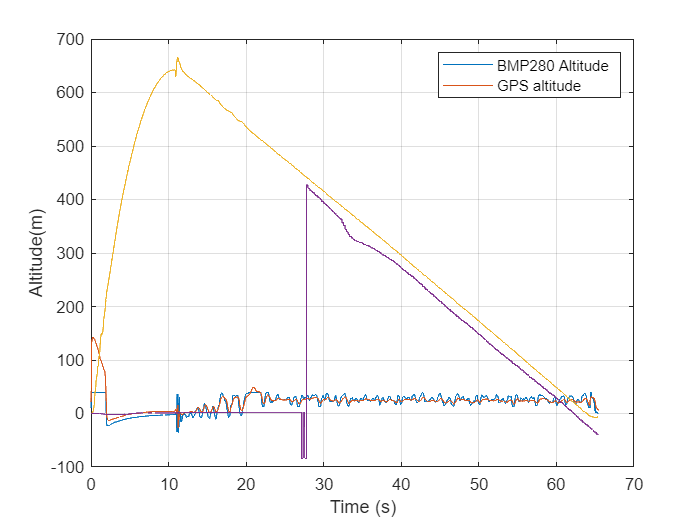

gpsLat = data(:, 21);
gpsLon = data(:, 22);
gpsAlt = data(:, 23);
gpsAlt = gpsAlt - gpsAlt(1);
DRZ = data(:);
BNOaccx = data(:,9);
ADXLaccx = data(:,15);

plot(time, bmpAlt)
hold on
plot(time, gpsAlt)
legend("BMP280 Altitude", "GPS altitude")
grid on
xlabel("Time (s)");
ylabel("Altitude(m)")
hold off



seaLevelHpa = 1024;
altitude = 44330 * (1.0 - ((bmpPressure/100) / seaLevelHpa).^0.1903);
altitude = altitude - altitude(1)

altitude =          0
         0
         0
         0
   -0.0578
   -0.0578
   -0.0578
         0
    0.0572
    0.1722


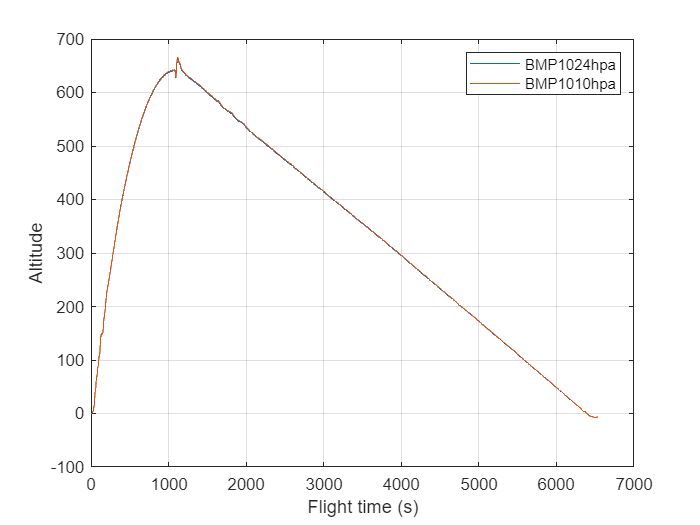

plot(altitude)
hold on
plot(bmpAlt)
grid on
ylabel("Altitude")
xlabel("Flight time (s)")
legend("BMP1024hpa", "BMP1010hpa")
hold off

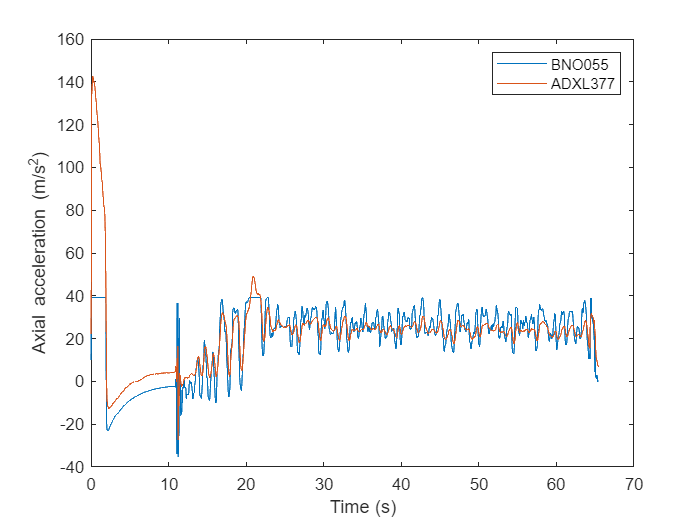


%plot(gpsLon)
%plot(gpsLat)
plot(time, BNOaccx)
hold on
plot(time, ADXLaccx)
legend("BNO055", "ADXL377")
xlabel("Time (s)");
ylabel("Axial acceleration (m/s^2)")


% hold off
% 
% ADXLvelx = cumtrapz(time(1:3000), ADXLaccx(1:3000));
% plot(time(1:3000), ADXLvelx)
% ylabel("Velocity")
% ADXLposx = cumtrapz(time(1:3000), ADXLvelx(1:3000));
% plot(time(1:3000), ADXLposx)
% ylabel("DRZ")